# Pulse width modulation

Copyright (C) 2021 Miodrag Bolic

  This program is free software: you can redistribute it and/or modify   it under the terms of the GNU General Public License as published by  the Free Software Foundation, either version 3 of the License, or  (at your option) any later version.  This program is distributed in the hope that it will be useful, but WITHOUT ANY WARRANTY; without even the implied warranty of MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the GNU General Public License for more details <https://www.gnu.org/licenses/>. 

This code was developed by Miodrag Bolic for the book PERVASIVE CARDIAC AND RESPIRATORY MONITORING DEVICES: [https://github.com/Health-Devices/CARDIAC-RESPIRATORY-MONITORING.](https://github.com/Health-Devices/CARDIAC-RESPIRATORY-MONITORING.) We acknowledge that we used the code developed by Sourangsu Banerji, 2013 at https://www.mathworks.com/matlabcentral/fileexchange/42168-pulse-width-modulation.

## PWM Signal generation

The code below shows a 10 Hz modulation waveform. The input signal is the sine wave with a frequency of 1 Hz. The code then generates the  the output PWM signal.

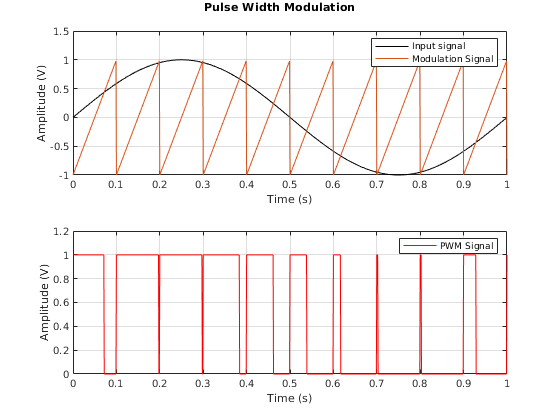

% This code has been modified from Sourangsu Banerji, 2013 at
% https://www.mathworks.com/matlabcentral/fileexchange/42168-pulse-width-modulation

clc;
clear all;
t = 0:0.001:1;
fc = 10; % the Frequency of Carrier Signal
fm = 1; % Frequency of the input signal
a = 1 ; %Amplitude of Modulation signal
b = 1; % Amplitude of the input signal
vc = a.*sawtooth(2*pi*fc*t);
vm = b.*sin(2*pi*fm*t);
n = length(vc);
for i = 1:n
    if (vm(i)>=vc(i))
        pwm1(i) = 1;
    else
        pwm1(i) = 0;
    end
end
% Representation of the Message Signal
subplot(2,1,1);
plot(t,vm,'black');
xlabel('Time (s)');
ylabel('Amplitude (V)');
ylim([-1, 1.5])
%title('Input Signal');
grid on;
% Representation of the Carrier Signal

hold on
plot(t,vc);

legend('Input signal', 'Modulation Signal');
grid on;
% Representation of the PWM Signal
subplot(2,1,2);
plot(t,pwm1,'red');
xlabel('Time (s)');
ylabel('Amplitude (V)');
%title('PWM Signal');
legend('PWM Signal');
ylim([0, 1.2])
%axis([0 1 0 2]);
grid on;
% Add title to the Overall Plot
ha = axes ('Position',[0 0 1 1],'Xlim',[0 1],'Ylim',[0 1],'Box','off','Visible','off','Units','normalized', 'clipping' , 'off');
text (0.5, 1,'\bf Pulse Width Modulation ','HorizontalAlignment','center','VerticalAlignment', 'top')